# Robotics2_4_2_2021

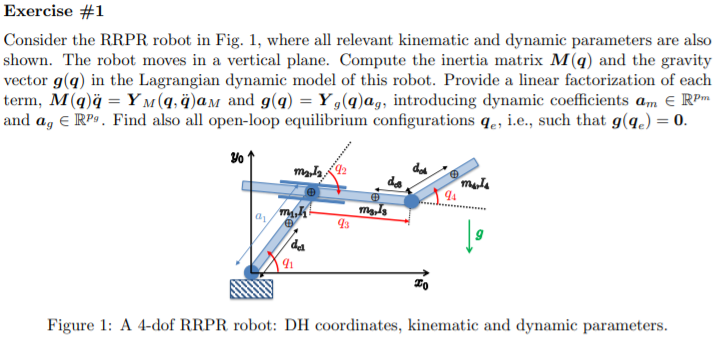

clear all, clc, close all
% This part is isolated from previous sectionclear;clc

% syms k q1(t) q2(t) q3(t)
% 1:revolute; 0:prismatic
sigma = [1,1,0,1];
n = length(sigma);
% t = sym('t', 'real');
q = sym('q_', [n 1],'real');
q_d= sym('q_d', [n 1],'real');
q_dot = sym('q_dot_', [n 1],'real');
q_ddot = sym('q_ddot_', [n 1],'real');
% 
dc = sym('dc', [n 1],'real');
% dc(6)=dc(6)
% k = sym('k', [n 1],'real');
l = sym('l', [n 1],'real');

m = sym('m', [n 1],'real');
m_p = sym('m_p','real');
%m(2)=m(2)+m_p
I = sym('I', [n 1],'real');
alpha_angle=sym('alpha','real')

$$alpha\_angle = \alpha$$

g0 = sym('g0','real');
% g=[-g0*sin(alpha_angle),-g0*cos(alpha_angle),0]';
% g=[0,-g0*sin(alpha_angle),0]';
[Rx,Ry,Rz]=getEulerRotationMatrices([-alpha_angle,0,0])

$$Rx = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\alpha \right) & \sin\left(\alpha \right)\\ 0 & -\sin\left(\alpha \right) & \cos\left(\alpha \right) \end{array}\right)$$

$$Ry = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

$$Rz = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

% g=[0,-g0*sin(alpha_angle),-g0*sin(alpha_angle)]'
g=[0,-g0,0]'

$$g = \left(\begin{array}{c} 0\\ -g_{0}\\ 0 \end{array}\right)$$

% g=vpa(expand(Rx*g))
R2Robot=['rrpr';'xxxx';sigma]    

R2Robot = 3×4 char array
    'rrpr'
    'xxxx'
    ' '


z = Gen_param(n);
z.sigmaD=R2Robot;

z.l=l;
z.q=q;
z.q_dot=q_dot;

z.dc=dc;
z.m=m;
z.I=I;
z.methodD=1%with DH table

z = struct with fields:
                  sigmaD: [3×4 char]
                       l: [4×1 sym]
                      l_: []
                       q: [4×1 sym]
                   q_dot: [4×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [4×1 sym]
                       m: [4×1 sym]
                       I: [4×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 4
                  angle_: [0    0    0    0]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1 1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
         

% z.dhTable=dhTable
z.firstParam='alpha';
% z.rc=[]
% z.movingframes=[]
z.angle_=sym(zeros(1,n));
% z.opt_expr={[l(1)+q(2)],[q(2)]};!! pay attention to this
% z.rcdefined=true;

%% the following assumptions are due to the inexistence of l1 and dc1   
% dc(2)=0
% l(2)=0
z.dc=dc;
z.l=l;
% xyonly=true
% [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% VarShortRobot.M
% angle_desired=[0,0]
% l(1)=0
% % l(1)=0 %don't do this because dc1 is going to dissaperar
z.opt_expr={[l(2),dc(2)],[0,0]};%use this instead


z.prismatic_CoM_method(3)=2;
[Pc,vc,w,T,Ti,M] = getGenericPC2(z);

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×4 char]
                       l: [4×1 sym]
                      l_: []
                       q: [4×1 sym]
                   q_dot: [4×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [4×1 sym]
                       m: [4×1 sym]
                       I: [4×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 4
                  angle_: [0    0    0    0]
               rcdefined: 1
                opt_expr: {[l2    dc2]  [0 0]}
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1 2 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_refe

si falla aquí está el error


$$a = l_{1}$$

d = 0

$$a = l_{2}$$

d = 0

anglerot = 1×3 cell array
    {4×4 sym}    {4×4 sym}    {4×4 sym}


$$a = l_{4}$$

d = 0

method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2}+\frac{{l_{1}}^{2}\,m_{2}\,{{\dot{q}}_{1}}^{2}}{2} \end{array}\right)$$

moving frames OFF!!


$$Ti = \left(\begin{array}{ccc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2}+\frac{{l_{1}}^{2}\,m_{2}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{I_{3}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2}+\frac{m_{3}\,\left({{\dot{q}}_{2}}^{2}\,{\left({\mathrm{dc}}_{3}-q_{3}\right)}^{2}+{{\dot{q}}_{1}}^{2}\,\left({{\mathrm{dc}}_{3}}^{2}-2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{3}\,l_{1}-2\,{\mathrm{dc}}_{3}\,q_{3}+{l_{1}}^{2}+2\,\cos\left(q_{2}\right)\,l_{1}\,q_{3}+{q_{3}}^{2}\right)+{{\dot{q}}_{3}}^{2}-{\dot{q}}_{1}\,{\dot{q}}_{2}\,\left(2\,{\mathrm{dc}}_{3}-2\,q_{3}\right)\,\left(q_{3}-{\mathrm{dc}}_{3}+l_{1}\,\cos\left(q_{2}\right)\right)+2\,l_{1}\,{\dot{q}}_{1}\,{\dot{q}}_{3}\,\sin\left(q_{2}\right)\right)}{2} \end{array}\right)$$

moving frames OFF!!


w

$$w = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ {\dot{q}}_{1} & {\dot{q}}_{1}+{\dot{q}}_{2} & {\dot{q}}_{1}+{\dot{q}}_{2} & {\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{4} \end{array}\right)$$

vc

$$vc = \begin{array}{l} \left(\begin{array}{cccc} -{\mathrm{dc}}_{1}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right) & -l_{1}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right) & \sigma_{3}+{\dot{q}}_{1}\,\left(\sin\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{3}-q_{3}\right)-l_{1}\,\sin\left(q_{1}\right)\right)+{\dot{q}}_{2}\,\sin\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{3}-q_{3}\right) & \sigma_{3}-{\dot{q}}_{1}\,\left(\sigma_{2}+l_{1}\,\sin\left(q_{1}\right)+{\mathrm{dc}}_{4}\,\sigma_{5}\right)-{\dot{q}}_{2}\,\left(\sigma_{2}+{\mathrm{dc}}_{4}\,\sigma_{5}\right)-{\mathrm{dc}}_{4}\,{\dot{q}}_{4}\,\sigma_{5}\\ {\mathrm{dc}}_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right) & l_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right) & \sigma_{1}-{\dot{q}}_{1}\,\left(\cos\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{3}-q_{3}\right)-l_{1}\,\cos\left(q_{1}\right)\right)-{\dot{q}}_{2}\,\cos\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{3}-q_{3}\right) & {\dot{q}}_{1}\,\left(\sigma_{4}+l_{1}\,\cos\left(q_{1}\right)+{\mathrm{dc}}_{4}\,\sigma_{6}\right)+{\dot{q}}_{2}\,\left(\sigma_{4}+{\mathrm{dc}}_{4}\,\sigma_{6}\right)+\sigma_{1}+{\mathrm{dc}}_{4}\,{\dot{q}}_{4}\,\sigma_{6}\\ 0 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\dot{q}}_{3}\,\sin\left(q_{1}+q_{2}\right)\\ \sigma_{2}=q_{3}\,\sin\left(q_{1}+q_{2}\right)\\ \sigma_{3}={\dot{q}}_{3}\,\cos\left(q_{1}+q_{2}\right)\\ \sigma_{4}=q_{3}\,\cos\left(q_{1}+q_{2}\right)\\ \sigma_{5}=\sin\left(q_{1}+q_{2}+q_{4}\right)\\ \sigma_{6}=\cos\left(q_{1}+q_{2}+q_{4}\right) \end{array}$$

T

Ti

M

$$M = \begin{array}{l} \left(\begin{array}{cccc} I_{1}+I_{2}+I_{3}+I_{4}+{{\mathrm{dc}}_{1}}^{2}\,m_{1}+{{\mathrm{dc}}_{3}}^{2}\,m_{3}+{{\mathrm{dc}}_{4}}^{2}\,m_{4}+{l_{1}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{3}+{l_{1}}^{2}\,m_{4}+m_{3}\,{q_{3}}^{2}+m_{4}\,{q_{3}}^{2}-2\,{\mathrm{dc}}_{3}\,m_{3}\,q_{3}+2\,{\mathrm{dc}}_{4}\,l_{1}\,m_{4}\,\cos\left(q_{2}+q_{4}\right)-2\,{\mathrm{dc}}_{3}\,l_{1}\,m_{3}\,\cos\left(q_{2}\right)+\sigma_{5}+2\,l_{1}\,m_{3}\,q_{3}\,\cos\left(q_{2}\right)+2\,l_{1}\,m_{4}\,q_{3}\,\cos\left(q_{2}\right) & \sigma_{2} & \sigma_{4} & \sigma_{3}\\ \sigma_{2} & I_{2}+I_{3}+I_{4}+{{\mathrm{dc}}_{3}}^{2}\,m_{3}+{{\mathrm{dc}}_{4}}^{2}\,m_{4}+m_{3}\,{q_{3}}^{2}+m_{4}\,{q_{3}}^{2}-2\,{\mathrm{dc}}_{3}\,m_{3}\,q_{3}+\sigma_{5} & \sigma_{7} & \sigma_{1}\\ \sigma_{4} & \sigma_{7} & m_{3}+m_{4} & \sigma_{7}\\ \sigma_{3} & \sigma_{1} & \sigma_{7} & m_{4}\,{{\mathrm{dc}}_{4}}^{2}+I_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{4}\,{{\mathrm{dc}}_{4}}^{2}+m_{4}\,q_{3}\,\cos\left(q_{4}\right)\,{\mathrm{dc}}_{4}+I_{4}\\ \sigma_{2}=I_{2}+I_{3}+I_{4}+{{\mathrm{dc}}_{3}}^{2}\,m_{3}+{{\mathrm{dc}}_{4}}^{2}\,m_{4}+m_{3}\,{q_{3}}^{2}+m_{4}\,{q_{3}}^{2}-2\,{\mathrm{dc}}_{3}\,m_{3}\,q_{3}+\sigma_{6}-{\mathrm{dc}}_{3}\,l_{1}\,m_{3}\,\cos\left(q_{2}\right)+\sigma_{5}+l_{1}\,m_{3}\,q_{3}\,\cos\left(q_{2}\right)+l_{1}\,m_{4}\,q_{3}\,\cos\left(q_{2}\right)\\ \sigma_{3}=I_{4}+{{\mathrm{dc}}_{4}}^{2}\,m_{4}+\sigma_{6}+{\mathrm{dc}}_{4}\,m_{4}\,q_{3}\,\cos\left(q_{4}\right)\\ \sigma_{4}=l_{1}\,m_{3}\,\sin\left(q_{2}\right)+\sigma_{7}+l_{1}\,m_{4}\,\sin\left(q_{2}\right)\\ \sigma_{5}=2\,{\mathrm{dc}}_{4}\,m_{4}\,q_{3}\,\cos\left(q_{4}\right)\\ \sigma_{6}={\mathrm{dc}}_{4}\,l_{1}\,m_{4}\,\cos\left(q_{2}+q_{4}\right)\\ \sigma_{7}=-{\mathrm{dc}}_{4}\,m_{4}\,\sin\left(q_{4}\right) \end{array}$$

[C,cac,Csubs,S] = getCs(M,q,q_dot);

>> Getting  the Christoffel’sym. Might take a while...


cac

$$cac = \begin{array}{l} \left(\begin{array}{c} \sigma_{4}+2\,l_{1}\,{\dot{q}}_{3}\,\cos\left(q_{2}\right)\,\left(m_{3}+m_{4}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)+\sigma_{1}-l_{1}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\,\left(2\,{\dot{q}}_{1}+{\dot{q}}_{2}\right)\,\sigma_{5}-\sigma_{2}-{\mathrm{dc}}_{4}\,l_{1}\,m_{4}\,\sin\left(q_{2}+q_{4}\right)\,\left({\dot{q}}_{2}+{\dot{q}}_{4}\right)\,\left(2\,{\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{4}\right)\\ \sigma_{4}+l_{1}\,{{\dot{q}}_{1}}^{2}\,\sin\left(q_{2}\right)\,\sigma_{5}+\sigma_{3}+\sigma_{1}-\sigma_{2}\\ -{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}\,\sigma_{5}-{\mathrm{dc}}_{4}\,m_{4}\,\cos\left(q_{4}\right)\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{4}\right)}^{2}-l_{1}\,{{\dot{q}}_{1}}^{2}\,\cos\left(q_{2}\right)\,\left(m_{3}+m_{4}\right)\\ \sigma_{3}+{\mathrm{dc}}_{4}\,m_{4}\,q_{3}\,\sin\left(q_{4}\right)\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}+\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,{\mathrm{dc}}_{4}\,m_{4}\,{\dot{q}}_{3}\,\cos\left(q_{4}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)\\ \sigma_{2}={\mathrm{dc}}_{4}\,m_{4}\,q_{3}\,{\dot{q}}_{4}\,\sin\left(q_{4}\right)\,\left(2\,{\dot{q}}_{1}+2\,{\dot{q}}_{2}+{\dot{q}}_{4}\right)\\ \sigma_{3}={\mathrm{dc}}_{4}\,l_{1}\,m_{4}\,{{\dot{q}}_{1}}^{2}\,\sin\left(q_{2}+q_{4}\right)\\ \sigma_{4}=2\,{\dot{q}}_{3}\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)\,\sigma_{5}\\ \sigma_{5}=m_{3}\,q_{3}-{\mathrm{dc}}_{3}\,m_{3}+m_{4}\,q_{3} \end{array}$$

vc(:,3)

$$ans = \left(\begin{array}{c} {\dot{q}}_{3}\,\cos\left(q_{1}+q_{2}\right)+{\dot{q}}_{1}\,\left(\sin\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{3}-q_{3}\right)-l_{1}\,\sin\left(q_{1}\right)\right)+{\dot{q}}_{2}\,\sin\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{3}-q_{3}\right)\\ {\dot{q}}_{3}\,\sin\left(q_{1}+q_{2}\right)-{\dot{q}}_{1}\,\left(\cos\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{3}-q_{3}\right)-l_{1}\,\cos\left(q_{1}\right)\right)-{\dot{q}}_{2}\,\cos\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{3}-q_{3}\right)\\ 0 \end{array}\right)$$

% qd



isMotor=false

isMotor = logical
   0


[g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l, m, dc, g, isMotor);

*** Computation of Potential Energy (Jacobian-based method) 


$$qall\_sincos\_comb = \left(\begin{array}{cccccccccccccccccccccccccccccc} \sin\left(q_{1}\right) & \sin\left(q_{2}\right) & \sin\left(q_{3}\right) & \sin\left(q_{4}\right) & \sin\left(q_{1}+q_{2}\right) & \sin\left(q_{1}+q_{3}\right) & \sin\left(q_{2}+q_{3}\right) & \sin\left(q_{1}+q_{4}\right) & \sin\left(q_{2}+q_{4}\right) & \sin\left(q_{3}+q_{4}\right) & \sin\left(q_{1}+q_{2}+q_{3}\right) & \sin\left(q_{1}+q_{2}+q_{4}\right) & \sin\left(q_{1}+q_{3}+q_{4}\right) & \sin\left(q_{2}+q_{3}+q_{4}\right) & \sin\left(q_{1}+q_{2}+q_{3}+q_{4}\right) & \cos\left(q_{1}\right) & \cos\left(q_{2}\right) & \cos\left(q_{3}\right) & \cos\left(q_{4}\right) & \cos\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{3}\right) & \cos\left(q_{2}+q_{3}\right) & \cos\left(q_{1}+q_{4}\right) & \cos\left(q_{2}+q_{4}\right) & \cos\left(q_{3}+q_{4}\right) & \cos\left(q_{1}+q_{2}+q_{3}\right) & \cos\left(q_{1}+q_{2}+q_{4}\right) & \cos\left(q_{1}+q_{3}+q_{4}\right) & \cos\left(q_{2}+q_{3}+q_{4}\right) & \cos\left(q_{1}+q_{2}+q_{3}+q_{4}\right) \end{array}\right)$$

$$PE = g_{0}\,\sin\left(q_{1}+q_{2}\right)\,\left(m_{3}\,q_{3}-{\mathrm{dc}}_{3}\,m_{3}+m_{4}\,q_{3}\right)+g_{0}\,\sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}+l_{1}\,m_{3}+l_{1}\,m_{4}\right)+{\mathrm{dc}}_{4}\,g_{0}\,m_{4}\,\sin\left(q_{1}+q_{2}+q_{4}\right)$$

$$PE\_short = g_{0}\,\sin\left(q_{1}+q_{2}\right)\,\left(m_{3}\,q_{3}-{\mathrm{dc}}_{3}\,m_{3}+m_{4}\,q_{3}\right)+g_{0}\,\sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}+l_{1}\,m_{3}+l_{1}\,m_{4}\right)+{\mathrm{dc}}_{4}\,g_{0}\,m_{4}\,\sin\left(q_{1}+q_{2}+q_{4}\right)$$

$$g\_q\_short = \begin{array}{l} \left(\begin{array}{c} g_{0}\,\cos\left(q_{1}+q_{2}\right)\,\left(m_{3}\,q_{3}-{\mathrm{dc}}_{3}\,m_{3}+m_{4}\,q_{3}\right)+g_{0}\,\cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}+l_{1}\,m_{3}+l_{1}\,m_{4}\right)+\sigma_{1}\\ g_{0}\,\cos\left(q_{1}+q_{2}\right)\,\left(m_{3}\,q_{3}-{\mathrm{dc}}_{3}\,m_{3}+m_{4}\,q_{3}\right)+\sigma_{1}\\ g_{0}\,\sin\left(q_{1}+q_{2}\right)\,\left(m_{3}+m_{4}\right)\\ \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{dc}}_{4}\,g_{0}\,m_{4}\,\cos\left(q_{1}+q_{2}+q_{4}\right) \end{array}$$

g_q_short

$$g\_q\_short = \begin{array}{l} \left(\begin{array}{c} g_{0}\,\cos\left(q_{1}+q_{2}\right)\,\left(m_{3}\,q_{3}-{\mathrm{dc}}_{3}\,m_{3}+m_{4}\,q_{3}\right)+g_{0}\,\cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}+l_{1}\,m_{3}+l_{1}\,m_{4}\right)+\sigma_{1}\\ g_{0}\,\cos\left(q_{1}+q_{2}\right)\,\left(m_{3}\,q_{3}-{\mathrm{dc}}_{3}\,m_{3}+m_{4}\,q_{3}\right)+\sigma_{1}\\ g_{0}\,\sin\left(q_{1}+q_{2}\right)\,\left(m_{3}+m_{4}\right)\\ \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{dc}}_{4}\,g_{0}\,m_{4}\,\cos\left(q_{1}+q_{2}+q_{4}\right) \end{array}$$

U{:}

$$ans = {\mathrm{dc}}_{1}\,g_{0}\,m_{1}\,\sin\left(q_{1}\right)$$

$$ans = g_{0}\,l_{1}\,m_{2}\,\sin\left(q_{1}\right)$$

$$ans = -g_{0}\,m_{3}\,\left(\sin\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{3}-q_{3}\right)-l_{1}\,\sin\left(q_{1}\right)\right)$$

$$ans = g_{0}\,m_{4}\,\left(q_{3}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)+{\mathrm{dc}}_{4}\,\sin\left(q_{1}+q_{2}+q_{4}\right)\right)$$

%[All, dynamicParamsReturn, a]= getDynamicParameters([M,(S),diag(g_q)],q,[g],2)
% [All, dynamicParamsReturn, a]= getDynamicParameters2([M,diag(g_q)],q,[l;g0]',2)


% [Msubs, dynamicParamsReturn, a]=getDynamicParameters2(M,q,l',2)%l')


[Msubs, dynamicParamsReturnM, aM]=getDynamicParameters3(M,q,[l],2)

>> Getting dynamic coefficients. Might take a while...


$$Msubs = \begin{array}{l} \left(\begin{array}{cccc} a_{7}-2\,a_{1}\,q_{3}+a_{4}\,{l_{1}}^{2}+a_{3}\,{q_{3}}^{2}-2\,a_{1}\,l_{1}\,\cos\left(q_{2}\right)+\sigma_{4}+2\,a_{3}\,l_{1}\,q_{3}\,\cos\left(q_{2}\right)+2\,a_{2}\,l_{1}\,\cos\left(q_{2}\right)\,\cos\left(q_{4}\right)-2\,a_{2}\,l_{1}\,\sin\left(q_{2}\right)\,\sin\left(q_{4}\right) & \sigma_{2} & \sigma_{3} & a_{5}+\sigma_{1}+\sigma_{6}-\sigma_{5}\\ \sigma_{2} & a_{6}-2\,a_{1}\,q_{3}+a_{3}\,{q_{3}}^{2}+\sigma_{4} & \sigma_{7} & a_{5}+\sigma_{1}\\ \sigma_{3} & \sigma_{7} & a_{3} & \sigma_{7}\\ a_{5}+\sigma_{1}+\sigma_{6}-\sigma_{5} & a_{5}+\sigma_{1} & \sigma_{7} & a_{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{2}\,q_{3}\,\cos\left(q_{4}\right)\\ \sigma_{2}=a_{6}-2\,a_{1}\,q_{3}+a_{3}\,{q_{3}}^{2}-a_{1}\,l_{1}\,\cos\left(q_{2}\right)+\sigma_{4}+a_{3}\,l_{1}\,q_{3}\,\cos\left(q_{2}\right)+\sigma_{6}-\sigma_{5}\\ \sigma_{3}=a_{3}\,l_{1}\,\sin\left(q_{2}\right)+\sigma_{7}\\ \sigma_{4}=2\,a_{2}\,q_{3}\,\cos\left(q_{4}\right)\\ \sigma_{5}=a_{2}\,l_{1}\,\sin\left(q_{2}\right)\,\sin\left(q_{4}\right)\\ \sigma_{6}=a_{2}\,l_{1}\,\cos\left(q_{2}\right)\,\cos\left(q_{4}\right)\\ \sigma_{7}=-a_{2}\,\sin\left(q_{4}\right) \end{array}$$

$$dynamicParamsReturnM = \left(\begin{array}{c} {\mathrm{dc}}_{3}\,m_{3}\\ {\mathrm{dc}}_{4}\,m_{4}\\ m_{3}+m_{4}\\ m_{2}+m_{3}+m_{4}\\ m_{4}\,{{\mathrm{dc}}_{4}}^{2}+I_{4}\\ m_{3}\,{{\mathrm{dc}}_{3}}^{2}+m_{4}\,{{\mathrm{dc}}_{4}}^{2}+I_{2}+I_{3}+I_{4}\\ m_{1}\,{{\mathrm{dc}}_{1}}^{2}+m_{3}\,{{\mathrm{dc}}_{3}}^{2}+m_{4}\,{{\mathrm{dc}}_{4}}^{2}+I_{1}+I_{2}+I_{3}+I_{4} \end{array}\right)$$

$$aM = \left(\begin{array}{c} a_{1}\\ a_{2}\\ a_{3}\\ a_{4}\\ a_{5}\\ a_{6}\\ a_{7} \end{array}\right)$$


[gsubs, dynamicParamsReturng, ag]=getDynamicParameters3(g_q,q,[g0],2)

>> Getting dynamic coefficients. Might take a while...


$$gsubs = \begin{array}{l} \left(\begin{array}{c} a_{4}\,g_{0}\,\cos\left(q_{1}\right)-\sigma_{8}+\sigma_{7}+\sigma_{5}-\sigma_{6}+\sigma_{1}-\sigma_{4}-\sigma_{3}-\sigma_{2}\\ \sigma_{7}-\sigma_{8}+\sigma_{5}-\sigma_{6}+\sigma_{1}-\sigma_{4}-\sigma_{3}-\sigma_{2}\\ a_{3}\,g_{0}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+a_{3}\,g_{0}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ \sigma_{1}-\sigma_{4}-\sigma_{3}-\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{2}\,g_{0}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{4}\right)\\ \sigma_{2}=a_{2}\,g_{0}\,\cos\left(q_{4}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{3}=a_{2}\,g_{0}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{4}\right)\\ \sigma_{4}=a_{2}\,g_{0}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{4}\right)\\ \sigma_{5}=a_{3}\,g_{0}\,q_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \sigma_{6}=a_{3}\,g_{0}\,q_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{7}=a_{1}\,g_{0}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{8}=a_{1}\,g_{0}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) \end{array}$$

$$dynamicParamsReturng = \left(\begin{array}{c} {\mathrm{dc}}_{3}\,m_{3}\\ {\mathrm{dc}}_{4}\,m_{4}\\ m_{3}+m_{4}\\ {\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}+l_{1}\,m_{3}+l_{1}\,m_{4} \end{array}\right)$$

$$ag = \left(\begin{array}{c} a_{1}\\ a_{2}\\ a_{3}\\ a_{4} \end{array}\right)$$


Msubs

$$Msubs = \begin{array}{l} \left(\begin{array}{cccc} a_{7}-2\,a_{1}\,q_{3}+a_{4}\,{l_{1}}^{2}+a_{3}\,{q_{3}}^{2}-2\,a_{1}\,l_{1}\,\cos\left(q_{2}\right)+\sigma_{4}+2\,a_{3}\,l_{1}\,q_{3}\,\cos\left(q_{2}\right)+2\,a_{2}\,l_{1}\,\cos\left(q_{2}\right)\,\cos\left(q_{4}\right)-2\,a_{2}\,l_{1}\,\sin\left(q_{2}\right)\,\sin\left(q_{4}\right) & \sigma_{2} & \sigma_{3} & a_{5}+\sigma_{1}+\sigma_{6}-\sigma_{5}\\ \sigma_{2} & a_{6}-2\,a_{1}\,q_{3}+a_{3}\,{q_{3}}^{2}+\sigma_{4} & \sigma_{7} & a_{5}+\sigma_{1}\\ \sigma_{3} & \sigma_{7} & a_{3} & \sigma_{7}\\ a_{5}+\sigma_{1}+\sigma_{6}-\sigma_{5} & a_{5}+\sigma_{1} & \sigma_{7} & a_{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{2}\,q_{3}\,\cos\left(q_{4}\right)\\ \sigma_{2}=a_{6}-2\,a_{1}\,q_{3}+a_{3}\,{q_{3}}^{2}-a_{1}\,l_{1}\,\cos\left(q_{2}\right)+\sigma_{4}+a_{3}\,l_{1}\,q_{3}\,\cos\left(q_{2}\right)+\sigma_{6}-\sigma_{5}\\ \sigma_{3}=a_{3}\,l_{1}\,\sin\left(q_{2}\right)+\sigma_{7}\\ \sigma_{4}=2\,a_{2}\,q_{3}\,\cos\left(q_{4}\right)\\ \sigma_{5}=a_{2}\,l_{1}\,\sin\left(q_{2}\right)\,\sin\left(q_{4}\right)\\ \sigma_{6}=a_{2}\,l_{1}\,\cos\left(q_{2}\right)\,\cos\left(q_{4}\right)\\ \sigma_{7}=-a_{2}\,\sin\left(q_{4}\right) \end{array}$$

dynamicParamsReturnM

$$dynamicParamsReturnM = \left(\begin{array}{c} {\mathrm{dc}}_{3}\,m_{3}\\ {\mathrm{dc}}_{4}\,m_{4}\\ m_{3}+m_{4}\\ m_{2}+m_{3}+m_{4}\\ m_{4}\,{{\mathrm{dc}}_{4}}^{2}+I_{4}\\ m_{3}\,{{\mathrm{dc}}_{3}}^{2}+m_{4}\,{{\mathrm{dc}}_{4}}^{2}+I_{2}+I_{3}+I_{4}\\ m_{1}\,{{\mathrm{dc}}_{1}}^{2}+m_{3}\,{{\mathrm{dc}}_{3}}^{2}+m_{4}\,{{\mathrm{dc}}_{4}}^{2}+I_{1}+I_{2}+I_{3}+I_{4} \end{array}\right)$$

gsubs

$$gsubs = \begin{array}{l} \left(\begin{array}{c} a_{4}\,g_{0}\,\cos\left(q_{1}\right)-\sigma_{8}+\sigma_{7}+\sigma_{5}-\sigma_{6}+\sigma_{1}-\sigma_{4}-\sigma_{3}-\sigma_{2}\\ \sigma_{7}-\sigma_{8}+\sigma_{5}-\sigma_{6}+\sigma_{1}-\sigma_{4}-\sigma_{3}-\sigma_{2}\\ a_{3}\,g_{0}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+a_{3}\,g_{0}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ \sigma_{1}-\sigma_{4}-\sigma_{3}-\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{2}\,g_{0}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{4}\right)\\ \sigma_{2}=a_{2}\,g_{0}\,\cos\left(q_{4}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{3}=a_{2}\,g_{0}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{4}\right)\\ \sigma_{4}=a_{2}\,g_{0}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{4}\right)\\ \sigma_{5}=a_{3}\,g_{0}\,q_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \sigma_{6}=a_{3}\,g_{0}\,q_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{7}=a_{1}\,g_{0}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{8}=a_{1}\,g_{0}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) \end{array}$$

dynamicParamsReturng

$$dynamicParamsReturng = \left(\begin{array}{c} {\mathrm{dc}}_{3}\,m_{3}\\ {\mathrm{dc}}_{4}\,m_{4}\\ m_{3}+m_{4}\\ {\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}+l_{1}\,m_{3}+l_{1}\,m_{4} \end{array}\right)$$

% M

% Msubs = All(:,1:4)
% Ssubs = All(:,4:6)
% gSubs = diag(All(:,5:8))
% FSubs = All(:,10:12)

% torqueSubs = Msubs*qdd + Ssubs*qd + gSubs +FSubs*qd
a_orderM=aM([1,4,5,3,6,2])

$$a\_orderM = \left(\begin{array}{c} a_{1}\\ a_{4}\\ a_{5}\\ a_{3}\\ a_{6}\\ a_{2} \end{array}\right)$$

[YM,YM_short]=getLinearParametrization(Msubs*q_ddot,a_orderM)

$$YM = \begin{array}{l} \left(\begin{array}{cccccc} -{\ddot{q}}_{2}\,\sigma_{2}-{\ddot{q}}_{1}\,\left(2\,q_{3}+2\,l_{1}\,\cos\left(q_{2}\right)\right) & {l_{1}}^{2}\,{\ddot{q}}_{1} & {\ddot{q}}_{4} & {\ddot{q}}_{2}\,\sigma_{1}+{\ddot{q}}_{1}\,\left({q_{3}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,q_{3}\right)+l_{1}\,{\ddot{q}}_{3}\,\sin\left(q_{2}\right) & {\ddot{q}}_{2} & {\ddot{q}}_{2}\,\left(\sigma_{3}+\sigma_{6}-\sigma_{5}\right)-{\ddot{q}}_{3}\,\sin\left(q_{4}\right)+{\ddot{q}}_{4}\,\sigma_{4}+{\ddot{q}}_{1}\,\left(\sigma_{3}+2\,l_{1}\,\cos\left(q_{2}\right)\,\cos\left(q_{4}\right)-2\,l_{1}\,\sin\left(q_{2}\right)\,\sin\left(q_{4}\right)\right)\\ -2\,q_{3}\,{\ddot{q}}_{2}-{\ddot{q}}_{1}\,\sigma_{2} & 0 & {\ddot{q}}_{4} & {\ddot{q}}_{1}\,\sigma_{1}+{q_{3}}^{2}\,{\ddot{q}}_{2} & {\ddot{q}}_{1}+{\ddot{q}}_{2} & {\ddot{q}}_{1}\,\left(\sigma_{3}+\sigma_{6}-\sigma_{5}\right)-{\ddot{q}}_{3}\,\sin\left(q_{4}\right)+2\,q_{3}\,{\ddot{q}}_{2}\,\cos\left(q_{4}\right)+q_{3}\,{\ddot{q}}_{4}\,\cos\left(q_{4}\right)\\ 0 & 0 & 0 & {\ddot{q}}_{3}+l_{1}\,{\ddot{q}}_{1}\,\sin\left(q_{2}\right) & 0 & -{\ddot{q}}_{1}\,\sin\left(q_{4}\right)-{\ddot{q}}_{2}\,\sin\left(q_{4}\right)-{\ddot{q}}_{4}\,\sin\left(q_{4}\right)\\ 0 & 0 & {\ddot{q}}_{1}+{\ddot{q}}_{2}+{\ddot{q}}_{4} & 0 & 0 & {\ddot{q}}_{1}\,\sigma_{4}-{\ddot{q}}_{3}\,\sin\left(q_{4}\right)+q_{3}\,{\ddot{q}}_{2}\,\cos\left(q_{4}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={q_{3}}^{2}+l_{1}\,\cos\left(q_{2}\right)\,q_{3}\\ \sigma_{2}=2\,q_{3}+l_{1}\,\cos\left(q_{2}\right)\\ \sigma_{3}=2\,q_{3}\,\cos\left(q_{4}\right)\\ \sigma_{4}=q_{3}\,\cos\left(q_{4}\right)+\sigma_{6}-\sigma_{5}\\ \sigma_{5}=l_{1}\,\sin\left(q_{2}\right)\,\sin\left(q_{4}\right)\\ \sigma_{6}=l_{1}\,\cos\left(q_{2}\right)\,\cos\left(q_{4}\right) \end{array}$$

$$YM\_short = \begin{array}{l} \left(\begin{array}{cccccc} -{\ddot{q}}_{2}\,\sigma_{3}-{\ddot{q}}_{1}\,\left(2\,q_{3}+2\,c_{2}\,l_{1}\right) & {l_{1}}^{2}\,{\ddot{q}}_{1} & {\ddot{q}}_{4} & {\ddot{q}}_{2}\,\sigma_{1}+{\ddot{q}}_{1}\,\left({q_{3}}^{2}+2\,c_{2}\,l_{1}\,q_{3}\right)+l_{1}\,{\ddot{q}}_{3}\,s_{2} & {\ddot{q}}_{2} & {\ddot{q}}_{2}\,\sigma_{2}-{\ddot{q}}_{3}\,s_{4}+{\ddot{q}}_{4}\,\sigma_{4}+{\ddot{q}}_{1}\,\left(2\,c_{2,4}\,l_{1}+2\,c_{4}\,q_{3}\right)\\ -{\ddot{q}}_{1}\,\sigma_{3}-2\,q_{3}\,{\ddot{q}}_{2} & 0 & {\ddot{q}}_{4} & {\ddot{q}}_{1}\,\sigma_{1}+{q_{3}}^{2}\,{\ddot{q}}_{2} & {\ddot{q}}_{1}+{\ddot{q}}_{2} & {\ddot{q}}_{1}\,\sigma_{2}-{\ddot{q}}_{3}\,s_{4}+2\,c_{4}\,q_{3}\,{\ddot{q}}_{2}+c_{4}\,q_{3}\,{\ddot{q}}_{4}\\ 0 & 0 & 0 & {\ddot{q}}_{3}+l_{1}\,{\ddot{q}}_{1}\,s_{2} & 0 & -s_{4}\,\left({\ddot{q}}_{1}+{\ddot{q}}_{2}+{\ddot{q}}_{4}\right)\\ 0 & 0 & {\ddot{q}}_{1}+{\ddot{q}}_{2}+{\ddot{q}}_{4} & 0 & 0 & {\ddot{q}}_{1}\,\sigma_{4}-{\ddot{q}}_{3}\,s_{4}+c_{4}\,q_{3}\,{\ddot{q}}_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={q_{3}}^{2}+c_{2}\,l_{1}\,q_{3}\\ \sigma_{2}=c_{2,4}\,l_{1}+2\,c_{4}\,q_{3}\\ \sigma_{3}=2\,q_{3}+c_{2}\,l_{1}\\ \sigma_{4}=c_{2,4}\,l_{1}+c_{4}\,q_{3} \end{array}$$

% torqueSubs = Msubs*qdd + Ssubs*qd + gSubs +FSubs*qd
a_orderg=ag([2,3,1,4])

$$a\_orderg = \left(\begin{array}{c} a_{2}\\ a_{3}\\ a_{1}\\ a_{4} \end{array}\right)$$

[Yg,Yg_short]=getLinearParametrization(gsubs,a_orderg)

$$Yg = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & \sigma_{2} & \sigma_{3} & g_{0}\,\cos\left(q_{1}\right)\\ \sigma_{1} & \sigma_{2} & \sigma_{3} & 0\\ 0 & g_{0}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+g_{0}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & 0 & 0\\ \sigma_{1} & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=g_{0}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{4}\right)-g_{0}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{4}\right)-g_{0}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{4}\right)-g_{0}\,\cos\left(q_{4}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{2}=g_{0}\,q_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-g_{0}\,q_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{3}=g_{0}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)-g_{0}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) \end{array}$$

$$Yg\_short = \left(\begin{array}{cccc} c_{1,2,4}\,g_{0} & c_{1,2}\,g_{0}\,q_{3} & -c_{1,2}\,g_{0} & c_{1}\,g_{0}\\ c_{1,2,4}\,g_{0} & c_{1,2}\,g_{0}\,q_{3} & -c_{1,2}\,g_{0} & 0\\ 0 & g_{0}\,s_{1,2} & 0 & 0\\ c_{1,2,4}\,g_{0} & 0 & 0 & 0 \end{array}\right)$$